close("all"); clear; clc;

b = 0.2;
g = 9.81;
l = 0.3;
m = 1;

p = [b,g,l,m].';

A = pendulumStateMatrix([],p);
B = pendulumInputMatrix([],p);
C = eye(size(A));

sys = linearSys(A,B,[],C);

params.tFinal = 5;

ang_min = deg2rad(80);
ang_max = deg2rad(110);
w_min = 4;
w_max = 6;

x_min = [ang_min;w_min];
x_max = [ang_max;w_max];

params.R0 = zonotope(interval(x_min,x_max));
params.U = zonotope(interval(-0.1,0.1));
 
options.timeStep = 0.01;
options.zonotopeOrder = 10;
options.taylorTerms = 5;

R = reach(sys,params,options);

simOpt.points = 10;
simRes = simulateRandom(sys,params,simOpt);

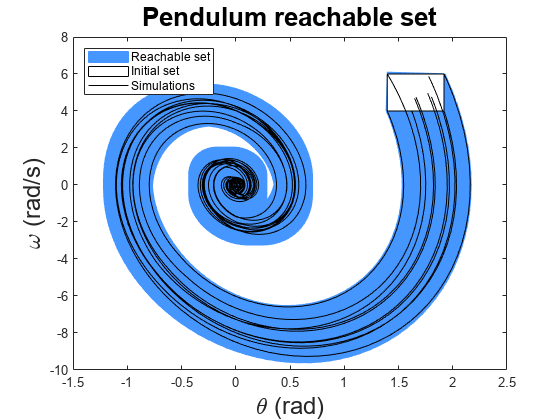

figure; hold on;
 
useCORAcolors("CORA:contDynamics")
plot(R,[1,2],'DisplayName','Reachable set')
plot(R.R0,[1,2],'DisplayName','Initial set')
plot(simRes,[1,2],'DisplayName','Simulations')
 
lg = legend('Location','southeast');
lg.Location = "northwest";
lg.Orientation = "vertical";
xlabel('\theta (rad)','FontSize',18)
ylabel('\omega (rad/s)','FontSize',18)
box("on")
title("Pendulum reachable set","FontSize",20)

saveas(gcf,"pendulum_plot","epsc");